This live-script runs solvers for the 1D acoustics equations via staggered grid FD methods.

In particular, the output pressure field is only stored at a single point in space.

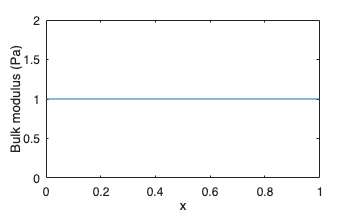

clear
close all
clc

% Computational space grids
dom_x = [0,1];
Nx = 401;

gsp_primal = GridSpace1D( Grid1DUnifPrimal(dom_x,Nx) );
gsp_dual   = GridSpace1D( Grid1DUnifDual(gsp_primal.x) );

% Medium parameters
medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_primal,medium);

kappa.plot;

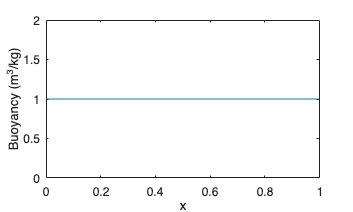

beta.plot;

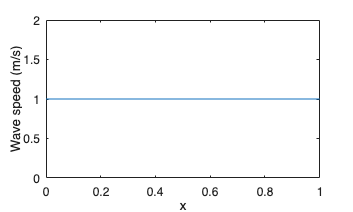

wspeed.plot;


% Computational time grid
dom_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)*gsp_primal.h/cMax;
Nt = ceil(diff(dom_t)/dt)+1;
dt = diff(dom_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = dom_t(1):dt:dom_t(2);

% Output locations and times
x_rcv = 0.3;
gsp_out = GridSpace1D( Grid1D(dom_x,x_rcv) );
times_out = linspace(dom_t(1),dom_t(2),81);

% Multipole point source
xc = 0.7;
tc = 0.2;
fpeak = 10;

monopole = MultipoleTerm1D(xc,0,...
    @(t) RickerWave(t,tc,fpeak),...
    TargetField="pressure");

dipole = MultipoleTerm1D(xc,1,...
    @(t) RickerWave(t,tc,fpeak),...
    Amplitude=gsp_primal.h, ...
    TargetField="pressure");

mps = MultipoleSource1D( ...
    [monopole,dipole], ...
    ApproximationOrder=4);
source = mps.discretize(gsp_primal,gsp_dual);

% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0.2, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Zero initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initialize solver
solver = AcousticSolver1D_PML( ...
    gsp_primal,times, ...
    gsp_out,times_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P,V] = solver.solve(p0,v0,Source=source);

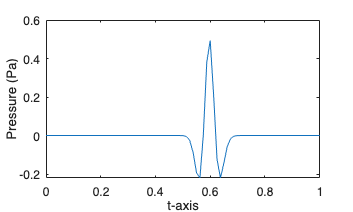

% Plotting results
figure
plot(times_out,P.values)
xlabel("t-axis")
ylabel(P.label+" ("+P.units+")")

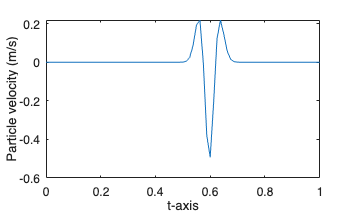


figure
plot(times_out,V.values)
xlabel("t-axis")
ylabel(V.label+" ("+V.units+")")